# Reverse flow - Rotor in forward flight


$$\textrm{Find}\;\textrm{the}\;\textrm{region}\;\textrm{of}\;\textrm{the}\;\textrm{flow}\;\textrm{field}\;\textrm{in}\;\textrm{which}\;\textrm{the}\;\textrm{tangential}\;\textrm{velocity}\;\textrm{component}\;U_t \;\textrm{became}\;\textrm{negative}:$$
 


$$u_t =\frac{U_t }{\Omega R}=\bar{r} +\mu \;\sin \left(\psi \right)=0$$



$$\mathrm{with}\;\mu =\frac{V_{\infty \;} \cos \left(\alpha \;\right)}{\Omega R}\;\mathrm{and}\;\bar{\;r} =\frac{r}{R}$$


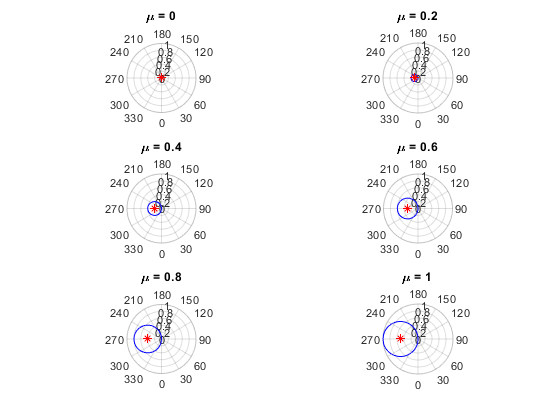

clc; clear; close all
vmu=0:0.2:1;
f=figure();
t=tiledlayout(3,2);
for i =1:length(vmu)
    mu=vmu(i);
    % creating a domain of radial station that gives real value of psi
    % y=asin(x) is real when x is in [-1,1] <=> r_bar is in [0, mu]
    r_bar=linspace(0,mu);
    psi1=asin(-r_bar/mu);   % 4th quadrant
    psi2=pi- psi1;          % 3th quadrant
    nexttile(t);
    p=polarplot(psi1,r_bar,'b',psi2,r_bar,'b',270*pi/180,mu/2,'*r');
    rlim([0 1])
    ax=gca;
    ax.ThetaZeroLocation='bottom';
    title(['\mu = ',num2str(mu)])
end